# Computational Methods in Physics (PHY4605) - **Data Types**

## Overview

There are many different data types, or classes, that you can work with in MATLAB. You can build matrices and arrays of floating-point and integer data, characters and strings, logical `true` and `false` values, and so on. Function handles connect your code with any MATLAB function regardless of the current scope. Tables, timetables, structures, and cell arrays provide a way to store dissimilar types of data in the same container. All of the fundamental MATLAB classes are shown in the diagram below:

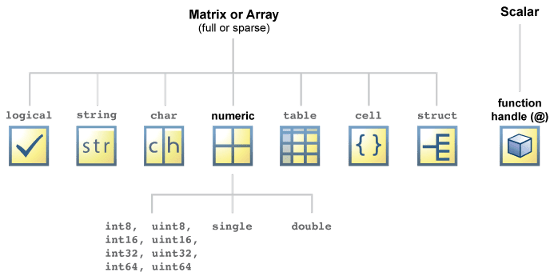

## Numeric Data

Numeric data in MATLAB include **signed** and **unsigned integers**, and **single-precision** and **double-precision floating-point** numbers:

- Double-precision arrays ([`double`](https://www.mathworks.com/help/matlab/ref/double.html)`)`

- Single-precision arrays ([`single`](https://www.mathworks.com/help/matlab/ref/single.html)`)`

- 8-bit signed integer arrays ([`int8`](https://www.mathworks.com/help/matlab/ref/int8.html)`)`

- 16-bit signed integer arrays ([`int16`](https://www.mathworks.com/help/matlab/ref/int16.html)`)`

- 32-bit signed integer arrays ([`int32`](https://www.mathworks.com/help/matlab/ref/int32.html)`)`

- 64-bit signed integer arrays ([`int64`](https://www.mathworks.com/help/matlab/ref/int64.html)`)`

- 8-bit unsigned integer arrays ([`uint8`](https://www.mathworks.com/help/matlab/ref/uint8.html)`)`

- 16-bit unsigned integer arrays ([`uint16`](https://www.mathworks.com/help/matlab/ref/uint16.html)`)`

- 32-bit unsigned integer arrays ([`uint32`](https://www.mathworks.com/help/matlab/ref/uint32.html)`)`

- 64-bit unsigned integer ([`uint64`](https://www.mathworks.com/help/matlab/ref/uint64.html)`)`

By default, MATLAB stores all numeric values as double-precision floating point.

## Characters and Strings

Character arrays and string arrays provide storage for text data.

A character array is a sequence of characters, just as a numeric array is a sequence of numbers. A typical use is to store short pieces of text as character vectors, such as:

Text = ['Hello World']
Code = double(Text)
Text([4, 5, 10])

Character vectors have two principal uses:

- To specify single pieces of text, such as file names and plot labels.

- To represent data that is encoded using characters. In such cases, you might need easy access to individual characters.

**A string array is a container for pieces of text**. String arrays provide a set of functions for working with text as data. You can create strings using double quotes, such as:

Text = "Greetings friend"

Text = 'Hello World'

Planets = ["Mercury", "Gemini", "Apollo"; "Skylab", "Skylab B", "ISS"]

Code =     72   101   108   108   111    32    87   111   114   108   100


Planets(2, 1)

ans = 'lol'

Strings can be manipulated more easily especially when dealing with large pieces of texts. You can index into, reshape, and concatenate string arrays using standard array operations, and you can append text to them using the `+` operator. If a string array represents numbers, then you can convert it to a numeric array using the `double` function:

Phrase = "A horse! A horse! My kingdom for a horse!"

Text = "Greetings friend"

ErasedPhrase = erase(Phrase, "!")

Planets = 2×3 string array
    "Mercury"    "Gemini"      "Apollo"
    "Skylab"     "Skylab B"    "ISS"   


LoweredPhrase = lower(Phrase)

ans = "Skylab"

UpperPhrase = upper(Phrase)
SplitPhrase = split(Phrase)
UniquePhrase = unique(SplitPhrase) 

Phrase = "A horse! A horse! My kingdom for a horse!"

AppendedPhrase = Phrase + " Withdraw, my lord! I'll help you to a horse."

ErasedPhrase = "A horse A horse My kingdom for a horse"

t = "777"

LoweredPhrase = "a horse! a horse! my kingdom for a horse!"

StringNumber = double("42")

UpperPhrase = "A HORSE! A HORSE! MY KINGDOM FOR A HORSE!"

## Dates and Time

The date and time data types namely **datetime, duration, and calendar duration** support efficient computations, comparisons, and formatted display of dates and times. Work with these arrays in the same way that you work with numeric arrays. You can add, subtract, sort, compare, concatenate, and plot date and time values. You also can represent dates and times as numeric arrays or as text:

Strings = {'2018-06-25 11:23', '2019-09-02 12:45'};

SplitPhrase = 9×1 string array
    "A"
    "horse!"
    "A"
    "horse!"
    "My"
    "kingdom"
    "for"
    "a"
    "horse!"


Datetimes = datetime(Strings, InputFormat = 'yyyy-MM-dd HH:mm')

UniquePhrase = 6×1 string array
    "A"
    "My"
    "a"
    "for"
    "horse!"
    "kingdom"


Datetimes = [Datetimes, datetime('now'), datetime('tomorrow'), datetime('yesterday')]

AppendedPhrase = "A horse! A horse! My kingdom for a horse! Withdraw, my lord! I'll help you to a horse."

The values in a **duration** array represent **elapsed times in units of fixed length**, such as hours, minutes, and seconds. You can create duration arrays that have specified time units using the `years`, `days`, `hours`, `minutes`, `seconds` and `miliseconds` functions. For example, to create an array that has elapsed times of 1, 2, and 3 hours, use the `hours` function:

Time = datetime('today') : years(35) : datetime('tomorrow')

t = "777"

StringNumber = 42

Durations = hours(1:3)
LongerDurations = Durations + minutes(30:5:40) + seconds([12, 24, 91])

Datetimes = 1×2 datetime array
   25-Jun-2018 11:23:00   02-Sep-2019 12:45:00


ElapsedDuration = Datetimes(2) - Datetimes(1)

Datetimes = 1×5 datetime array
   25-Jun-2018 11:23:00   02-Sep-2019 12:45:00   24-Oct-2024 09:44:01   25-Oct-2024 00:00:00   23-Oct-2024 00:00:00


ElapsedDays = years(ElapsedDuration)

The values in **calendar duration arrays represent elapsed time in calendar units of variable length**. For example, the number of days in a month depends on the particular month of the year. Use calendar duration arrays to simplify calculations on datetime arrays that involve calendar units, such as days and months.

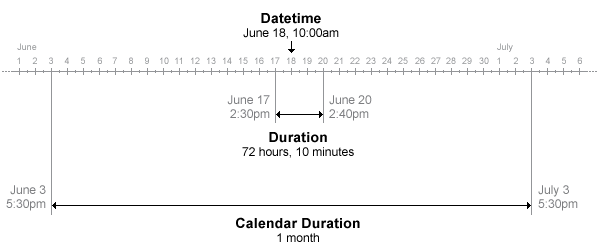

## Cells

A cell array is a data type with indexed data containers called cells, where each cell can contain any type of data. Cell arrays commonly contain either **lists of text, combinations of text and numbers, or numeric arrays of different sizes**. When you have data to put into a cell array, create the array using the cell array construction operator, `{}`.

MixedData = {1, 2, datetime('yesterday');...

Time = datetime
   24-Oct-2024


    'Lorem ipsum', rand(5, 10), {11; 22; 33}}

Refer to sets of cells by enclosing indices in smooth parentheses, `()`. Access the contents of cells by indexing with curly braces, `{}`:

CellElement = MixedData(2, 2)            % Accessing an element of the cell array

Durations = 1×3 duration array
   1 hr   2 hr   3 hr


Page = MixedData{2, 2}                   % Accessing the content of the element

LongerDurations = 1×3 duration array
   1.5033 hr     2.59 hr   3.6919 hr


PageElement = MixedData{2, 2}(:, 2)   % Accessing some elements of the content

ElapsedDuration = duration
   10417:22:00


## Structures

A structure array is a data type that **groups related data using data containers called fields**. Each field can contain any type of data. Access data in a field using dot notation of the form `StructName``.``FieldName`. The following creates a structure by adding fields to it using dot notation. The fields contain x- and `y`-values for a sine wave, and text that describes the data:

TrigoFuncs = struct;

ElapsedDays = 1.1884

TrigoFuncs.XPoints = linspace(0, 2*pi);
TrigoFuncs.YPoints = sin(TrigoFuncs.XPoints);
TrigoFuncs.Labels = {'y = sin(x)', 'x', 'sin(x)'}

You can add more elements to the existing structure array by using index. The following adds a second element to the `TrigoFuncs` structure:

TrigoFuncs(2).XPoints = linspace(0, 2*pi);
TrigoFuncs(2).YPoints = cos(TrigoFuncs(2).XPoints);

MixedData = 2×3 cell array
    {[          1]}    {[        2]}    {[23-Oct-2024]}
    {'Lorem ipsum'}    {5×10 double}    {3×1 cell     }


TrigoFuncs(2).Labels = {'y = cos(x)', 'x', 'cos(x)'}

The contents of the structure can be accessed using the dot notation and indices:

Tiles = tiledlayout('flow');

CellElement = 1×1 cell array
    {5×10 double}


title(Tiles, 'Sine and cosine functions');

Page =     0.6744    0.2250    0.3414    0.3681    0.4931    0.4892    0.0503    0.2736    0.3380    0.1454
    0.5567    0.1132    0.2792    0.1188    0.3433    0.1652    0.2984    0.8822    0.5968    0.0849
    0.5284    0.6509    0.7594    0.2924    0.6759    0.0115    0.1945    0.2224    0.9459    0.0104
    0.6521    0.0965    0.3797    0.9627    0.6695    0.7254    0.2030    0.2228    0.4620    0.7158
    0.7092    0.8414    0.2053    0.5497    0.1126    0.0315    0.4239    0.7467    0.3238    0.8414


PageElement =     0.2250
    0.1132
    0.6509
    0.0965
    0.8414


nexttile;
plot(TrigoFuncs(1).XPoints, TrigoFuncs(1).YPoints);
title(TrigoFuncs(1).Labels{1});
xlabel(TrigoFuncs(1).Labels{2});
ylabel(TrigoFuncs(1).Labels{3});

nexttile;
plot(TrigoFuncs(2).XPoints, TrigoFuncs(2).YPoints);
title(TrigoFuncs(2).Labels{1});
xlabel(TrigoFuncs(2).Labels{2});
ylabel(TrigoFuncs(2).Labels{3});

## Tables and Timetables

**Table** is a data type suitable for **column-oriented or tabular data** that is often stored as columns in a **text file or in a spreadsheet**. Tables consist of rows and column-oriented variables. Each variable in a table can have a different data type and a different size with the one restriction that each variable must have the same number of rows.

As an example, we want to store data about a group of patients in a table. First, workspace variables that have the patient data are created. The variables can have any data types but must have the same number of rows. Then, the variables are collated in a table called `PatientTable`:

LastName = {'Sanchez';'Johnson';'Li';'Diaz';'Brown'}
Age = [38; 43; 38; 40; 49]
Smoker = logical([1; 0; 1; 0; 1])
Weight = [71; 69; 64; 67; 64]
Height = [176; 163; 131; 133; 119]
BloodPressure = [124 93; 109 77; 125 83; 117 75; 122 80]

PatientTable = table(LastName, Age, Smoker, Height, Weight, BloodPressure)

Similar to structure, the contents can be accessed by dot notation and indices:

PatientTable(:, ["LastName", "Smoker"])
PatientTable(:, [2, 5])


PatientLastNames = PatientTable.LastName
PatientDataNo2 = PatientTable(2, :)
PatientNo4BP = PatientTable.BloodPressure(4, :)     % Accessing using dot notation
PatientNo4BP = PatientTable{4, 'BloodPressure'}     % Accessing using indices

**Timetable** is similar to table, with some key differences: it **associates a time with each row** as well as provides time-specific functions to align, combine, and perform calculations with time-stamped data in one or more timetables.

RandomTimes = datetime('today') + days(randi([-365, 365], 5, 1));
PatientTimetable = table2timetable(PatientTable, RowTimes = RandomTimes)

## STEM Spotlight 💡: Worldwide Earthquakes

The year 2021 has witnessed several significant earthquakes worldwide. In February, Japan was hit by a 7.3 magnitude earthquake near Fukushima, causing immense damage and numerous injuries. In April, Indonesia experienced a 6.0 magnitude earthquake in Java, killing eight people and injuring over a thousand others. In May, northeastern China suffered a 6.6 magnitude earthquake, resulting in eight deaths and over 200 injuries. These occurrences serve as a warning of the power of nature and the importance of preparation for disasters.

The following script extracts an earthquake catalogue occured in 2021 from a spredsheet and performs some statistical and graphical analyses:

QuakeTable = readtable('earthquakes-2021.csv')

LastName = 5×1 cell array
    {'Sanchez'}
    {'Johnson'}
    {'Li'     }
    {'Diaz'   }
    {'Brown'  }


Age =     38
    43
    38
    40
    49


QuakeTable.time = datetime(QuakeTable.time, InputFormat = 'yyyy-MM-dd''T''HH:mm:ss.SSS''Z''')

Smoker = 5×1 logical array
   1
   0
   1
   0
   1


Weight =     71
    69
    64
    67
    64


geobubble(QuakeTable.latitude, QuakeTable.longitude, QuakeTable.mag,...

Height =    176
   163
   131
   133
   119


    Basemap = 'grayland', SizeLegendTitle = 'Magnitude');

BloodPressure =    124    93
   109    77
   125    83
   117    75
   122    80



histogram(QuakeTable.mag)

PatientTable = 5×6 table
     LastName      Age    Smoker    Height    Weight    BloodPressure
    ___________    ___    ______    ______    ______    _____________

    {'Sanchez'}    38     true       176        71       124     93  
    {'Johnson'}    43     false      163        69       109     77  
    {'Li'     }    38     true       131        64       125     83  
    {'Diaz'   }    40     false      133        67       117     75  
    {'Brown'  }    49     true       119        64       122     80  


xlabel('Magnitude'); ylabel('Occurrences');
title('Histogram of earthquake magnitudes');


ans = 5×2 table
     LastName      Smoker
    ___________    ______

    {'Sanchez'}    true  
    {'Johnson'}    false 
    {'Li'     }    true  
    {'Diaz'   }    false 
    {'Brown'  }    true  


ans = 5×2 table
    Age    Weight
    ___    ______

    38       71  
    43       69  
    38       64  
    40       67  
    49       64  



ModerateQuakes = QuakeTable(QuakeTable.mag >= 5, :);

PatientLastNames = 5×1 cell array
    {'Sanchez'}
    {'Johnson'}
    {'Li'     }
    {'Diaz'   }
    {'Brown'  }


plot(dateshift(ModerateQuakes.time, 'start', 'day'), ModerateQuakes.mag, '*');

PatientDataNo2 = 1×6 table
     LastName      Age    Smoker    Height    Weight    BloodPressure
    ___________    ___    ______    ______    ______    _____________

    {'Johnson'}    43     false      163        69       109     77  


xlabel('Date'); ylabel('Magnitude');

PatientNo4BP =    117    75


title('Date versus magnitude scatter plot');

PatientNo4BP =    117    75


QuakeTable = 15451×22 table
                time                latitude    longitude    depth     mag    magType    nst    gap    dmin     rms      net            id                    updated                                   place                              type         horizontalError    depthError    magError    magNst       status       locationSource    magSource
    ____________________________    ________    _________    ______    ___    _______    ___    ___    ____

QuakeTable = 15451×22 table
            time            latitude    longitude    depth     mag    magType    nst    gap    dmin     rms      net            id                    updated                                   place                              type         horizontalError    depthError    magError    magNst       status       locationSource    magSource
    ____________________    ________    _________    ______    ___    _______    ___    ___    _____    <s

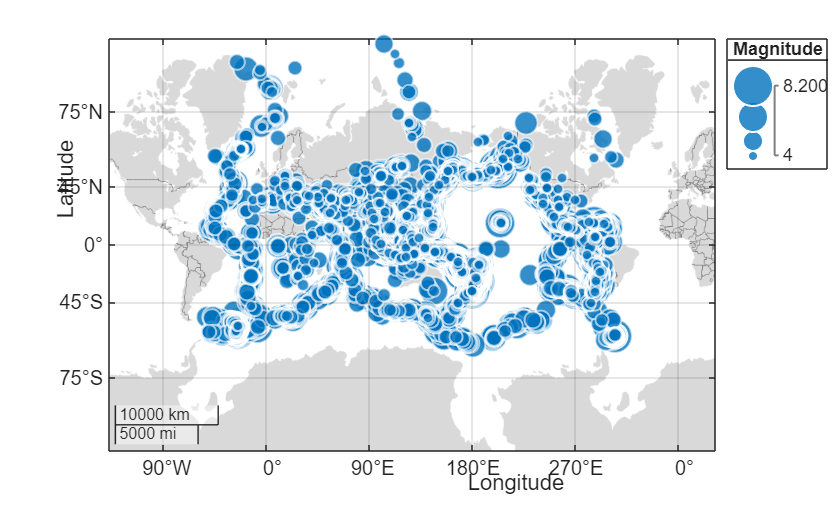

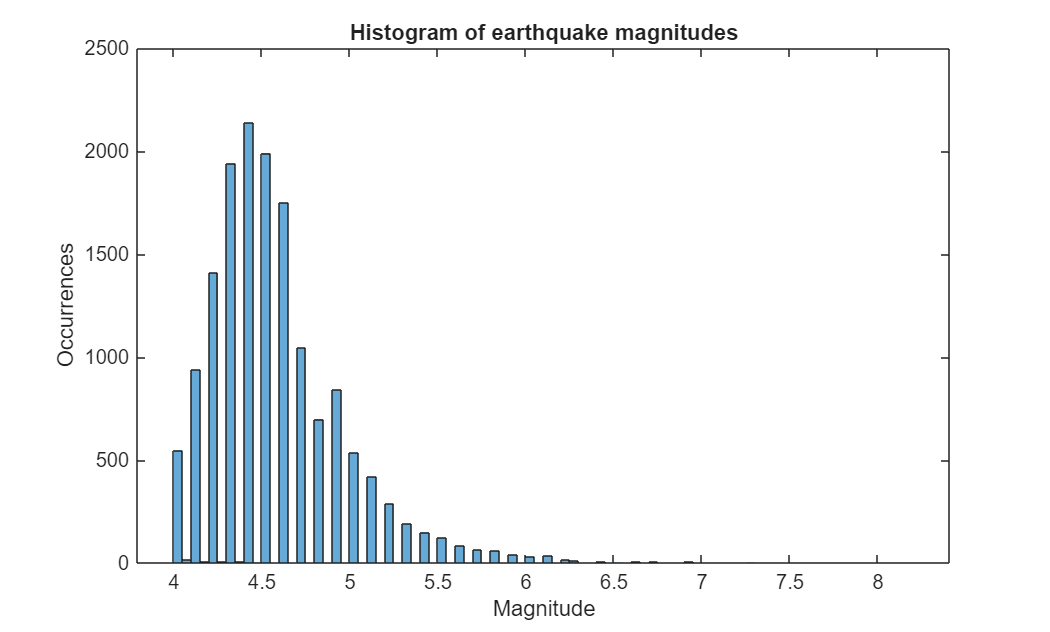

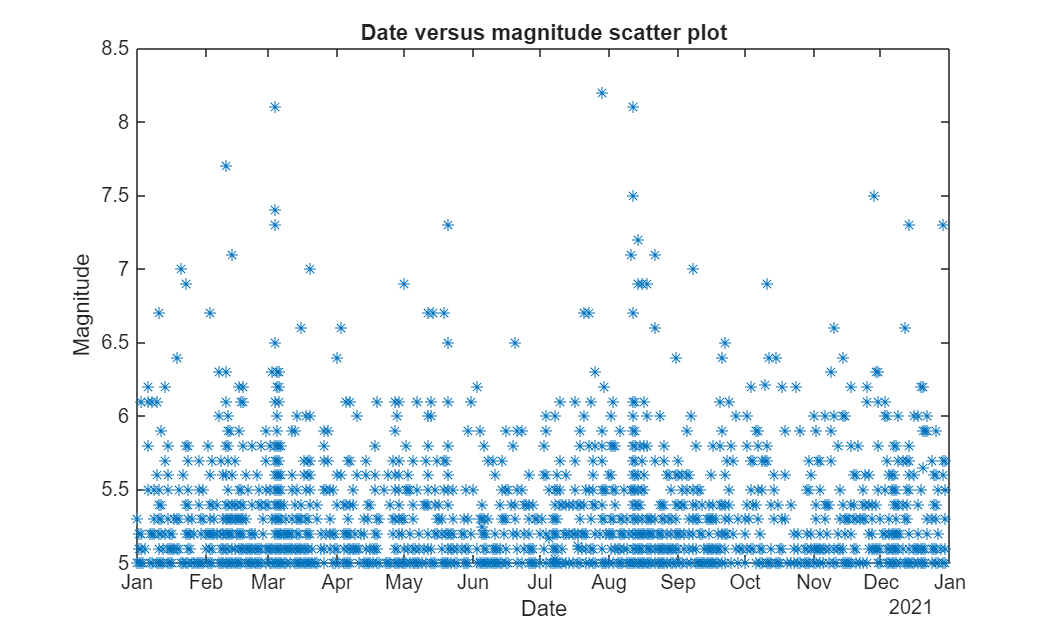

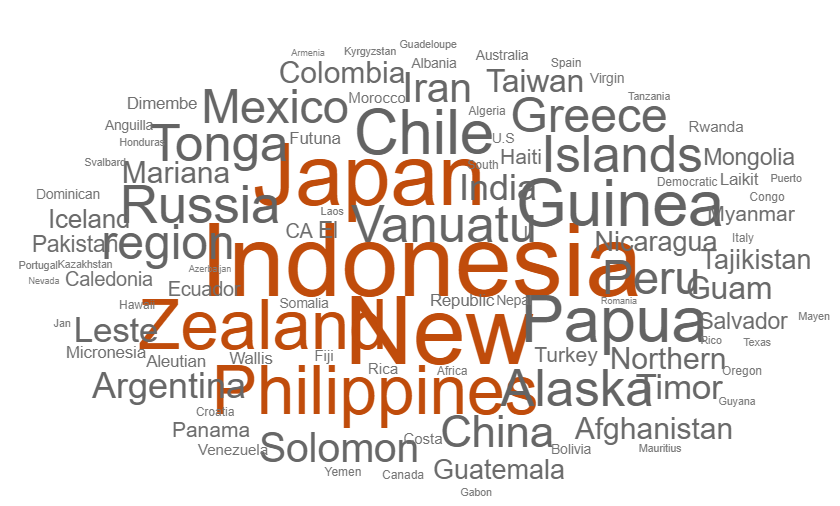


Countries = rmmissing(extractAfter(QuakeTable.place, ","));
wordcloud(Countries);
title('Country of earthquakes');